# Cathal Ryan 16401146

# Assignment 3 - Advanced Signal Processing

## Introduction

We are given an audio file "noisy_voices.wav", which consists of a sound recording where a wanted signal has been corrupted by a significant amount of additive interference. We are tasked with cleaning up the signal, making it intelligible and so it can be listened to with some comfort.

## Early Analysis of the Signal

We begin the task by listening to the signal and considering the task at hand. We can then view the signal in the time domain, and view the frequency spectrum of the signal by employing the fft. We can then also view the power spectral density to view how the power of the signal is distributed over frequency.

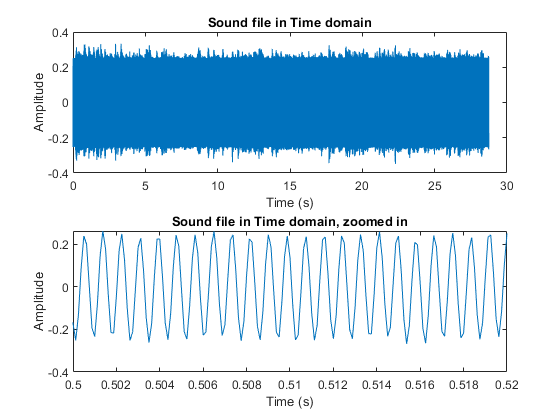

[x,Fs] = audioread('noisy_voices.wav'); % The data is read in as the vector x, while the sampling frequency is read in as Fs
%soundsc(x); %commented out so we dont hear it every time!
t=0:1/Fs:length(x)*1/Fs-1/Fs; %time vector, in seconds
subplot(211)
plot(t,x); % Time domain plot
title("Sound file in Time domain");
xlabel('Time (s)') 
ylabel('Amplitude') 
subplot(212)
plot(t,x); %Zoomed in time domain plot
xlim([0.5 0.52])
title("Sound file in Time domain, zoomed in");
xlabel('Time (s)') 
ylabel('Amplitude') 

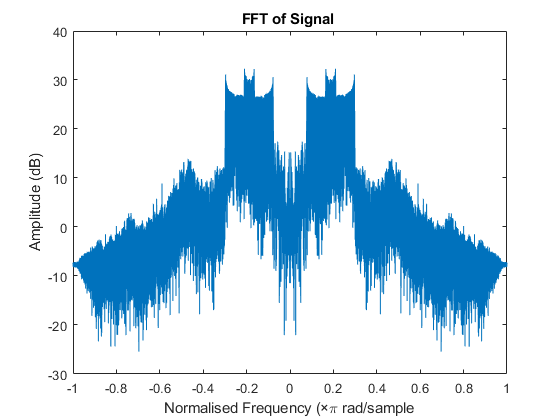

figure
F=abs(fftshift(fft(x))); %Find in Frequency Domain with fft
w=-1:(2/length(x)):1-2/length(x); %normalise frequency axis
plot(w, 10*log10(F)); %plot fft 
title("FFT of Signal ");
xlabel('Normalised Frequency (×\pi rad/sample') 
ylabel('Amplitude (dB)');

pwelch(x); %Find power spectral density

'pwelch' requires Signal Processing Toolbox.

We hear a loud, dynamic jamming frequency which overrides a recorded speech signal. The tone of this interference alternates gradually between a higher pitch and lower pitch. We can hear that the recorded speech signal sounds like a radio broadcast of some sort, which is then changed to a foreign launguage. This signal is being overpowered by the interference.

This corresponds well to what we see in the power spectrum of the signal, in which a set of frequencies between around 313 and 1186 Hz have a power several orders of magnitude higher than the rest of the signal. These are the frequencies of the noise. We see in the time domain that the signal is nearly 30 seconds long. When we zoom in on the figure, we see that the signal is sinusoidal in nature, with some movement. The sinusoidal component is the noise frequency at this point in time, while the movement up and down is the speech signal we wish to obtain.

The dynamic nature of this interference makes the short-time Fourier transform (STFT) useful in this case. The STFT provides the time-localised frequency information for situations in which frequency components of a signal vary over time. A good way to visualise the STFT is the spectrogram, which we will use in the following piece of code.

% 500 length windows with 250 overlap gives us good resolution.
spectrogram(x,500,250,500,Fs,'yaxis')
title('Spectrogram of noisyvoices.wav')

The spectrogram corresponds well to what was previously seen. There is a changing jamming frequency of much higher amplitude in the signal which we aim to remove. We can see in the spectrogram that the frequency of this noise varies between values similar to that suggested peviously.

We aim to remove this noise from the signal. This can be done in the time and frequency domains. We will primarily look at a frequency domain approach.

## Frequency Domain Approach

If the frequency of the interference signal was not changing, our solution to this problem would be simple: Detect the intereference frequency and apply a suitable notch filter. However, our task is not so simple as the frequency of this signal is constantly changing. Moreover, the frequency of the interference is always well within the expected range of human speech, meaning we cannot apply a simple bandstop filter across the interference frequency range.

The proposed solution to this problem is to divide the sequence into smaller sequences. With smaller sequences, the frequency can be assumed constant and a notch filter can be applied to remove the frequency of the interference within this time. By zooming in on the spectrogram, we can observe how we can make this assumption.

%Get spectrogram as before, but limit the x axis to zoom in
spectrogram(x,500,250,500,Fs,'yaxis')
title('Spectrogram of small segment of signal')
xlim([6.58 6.65]) 

As we can see, the frequency of the interference is reasonably constant across this small time interval. Therefore, if we were to apply a suitable notch filter to this segment, we can remove the jamming frequency. If we added up each segment after apply a filter to each, we should expect a reconstructed signal with these interference frequencies removed, without wrecking the speech signal. 

**Notch Filter Analysis**

Let us develop this first consideration of our algorithm in the following code, in which we inspect an arbitrarily chosen segment and apply a notch filter

x1 = x(20001:20500); % Arbitrarily chosen segment of length 500.
X = abs(fftshift(fft(x1))); % Find fft
[maxval,index] = max(X); %get the max value (frequency and where it occured.
frequ=1-2*((index-1)/length(X)); %find the frequency in normalised units.
[b,a]=iirnotch(frequ,0.1); %create filter, bandwidth chosen arbitrarily
x1_filt=filter(b,a,filter(b,a,x1)); %apply filter twice to get necessary attenuation.
X1_filt = abs(fftshift(fft(x1_filt))); % Find fft
w=-1:(2/length(X)):1-2/length(X); %frequencies normalised
plot(w,X) %original sequence fft
title("FFT of Original Sample vs Filtered Sample ");
xlabel('Normalised Frequency (×\pi rad/sample') 
ylabel('Amplitude (dB)');
hold on
w=-1:(2/length(X1_filt)):1-2/length(X1_filt);
plot(w,(X1_filt)) %filtered sequence fft
ylim([0 2])
legend('Original Sample','Filtered Sample')
figure
% VIEW IN TIME DOMAIN
t=0:1/Fs:length(x1)*1/Fs-1/Fs;
subplot(211);
plot(t,x1); %original
title("Original Sample in Time Domain");
xlabel('Time (s)') 
ylabel('Amplitude') 
subplot(212);
plot(t,x1_filt); %filtered
title("Filtered Sample in Time Domain");
xlabel('Time (s)') 
ylabel('Amplitude') 

The bandwidth of a notch filter is characterised by the equation $\textrm{BW}=\frac{W_0 }{Q}$ in which BW is the bandwidth of the notch, $W_0$ is the centre frequency and Q is the quality factor. Notch filters have high Q factor, with the Q factor being related to the energy storage of the filter. 

Generally all filters have some transient response, in which it takes a while for the filter to "settle down" towards the expected output. The settling period is called the transient response, while the steady-state response follows. Increasing the Q factor of the notch filter, and hence decreasing the bandwidth, results in larger transient time, as higher Q results in a lower rate of energy loss, and oscillations in the output die out slower.

We can see this transient response in the time-domain plot of the filtered signal. The signal oscillates at the beginning, with an amplitude of the original signal. This must be dealt with if we are to signal the filter correctly. We can see that the response lasts for around 6ms, around 10% of the total time.

The transient response is why we choose to use an IIR notch filter rather than an FIR bandstop filter. The length of the transient depends upon filter order, and IIR filters can be constructed with a much lower order than FIR counterparts for meeting equivalent magnitude specifications.

We can see in the frequency domain plot that the noise frequency at this particular time sequence has been attenuated strongly. We have chosen to implement a notch with a bandwidth of 0.1 for this example. The choice of bandwidth must be taken carefully, as seen in its impact upon the transient state as it affects the Q factor. However, we also wish to guarantee attenuation of the frequencies which are near the centre noise frequency. We can see in the FFT of the original signal that signals surrounding this centre frequency have strong amplitudes. We wish to select a bandwidth which is wide enough to cover these surrounding frequencies, without attenuating other frequencies too strongly.

In this example, we choose to operate the notch filter twice in order to gain adequate attenuation of the interference frequency. This is necessary for our designed filter as the interference is much higher than the rest of the signal.  We notice that the notch filter does not provide a perfect gain of 1 in the passband. The filter is not ideal and thus we expect some discrepancies in the resulting filter output. These discrepancies are considerable when the notch filter is applied twice. However we can see that the general form of the frequency response is followed in the filter output, with no ripple evident. We can clearly see the interference frequency being heavily attenuated succesfully.

**Implementing our Algorithm**

We now aim to implement an algorithm with notch filters in order to clean up the signal. We intend to use a variable notch filter which attenuates the highest frequency of each time segment. 

The issue of the transient response of the filter output is to be solved by using overlapping sequences in time. By doing this, we can disregard the early stages of the filtered output of each segment, and consider only the middle part. We truncate both ends of the sequence, as this should allow for smoother transitions between each sequence.

We could also solve this transient response issue by multiplying each sequence by a raised cosine window, thus reducing the amplitude of the edges of each sequence. We choose not to implement this here, as the overlapping sequences should be sufficient, however it is commented out in the code giving the option to use a raised cosine window in conjunction with overlapping sequences.

The length of the sequences is an important consideration. If the sequences are too long, the assumption that there is only one large frequency component present is not accurate and thus a single notch filter will not be sufficient. If the sequences are too short, the transient response of the filters will overpower the signal and we will hear a loud "tapping" sound, of high freqyency. This tapping sound is the large amplitude spikes which are at the start of the filter output. If the sequences are too short the overlapping may not suffice, as the filtered sequence will have too long a transient response relative to its length.

N=500; %length of each sequence
D = 0.4; % Percentage overlap, 0.4=40%
OL=floor(N*D); %length of total overlap
OLhalf=floor(0.5*OL);%length of overlap on each side

for i=1:floor((length(x)-N)/(N-OL))
    y = x(1+(i-1)*(N-OL):N+(i-1)*(N-OL),:); %Take next sequence from the full signal
    % Apply FFT on signal, and find the maximum point, which is the centre
    % interference frequency
    X = abs((fftshift(fft(y))));
    [maxval,index] = max(X);
    % Convert what point in the FFT the maximum was found into a normalised
    % frequency.
    frequ=1-2*((index-1)/length(X));
    [b,a]=iirnotch(frequ,0.2); % Create notch filter around the centre frequency, with bandwidth 0.2
    x_filt = filter(b,a,filter(b,a,y)); %apply filter twice on segment
    
    %special case for first segment, no overlap at start
    if i==1
    xfiltered(1:N-OLhalf,:) = x_filt(1:N-OLhalf);
    else 
%   Can implement raised cosine with these three commented lines.     
%   k=1:length(x_filt(OLhalf+1:N-OLhalf));
%   wk = 0.9 - 0.1*cos(2*pi*k/(length(x_filt(OLhalf+1:N-OLhalf))));
%   xfiltered(1+N-OLhalf+(N-OL)*(i-2):(N-OLhalf)+(N-OL)*(i-1)) = wk'.*x_filt(OLhalf+1:N-OLhalf);

    % Otherwise, take the filtered segment, omitting the edges, and add it to the filtered final sequence 
    xfiltered(1+N-OLhalf+(N-OL)*(i-2):(N-OLhalf)+(N-OL)*(i-1)) = x_filt(OLhalf+1:N-OLhalf);

    end
end
%Play the audio, commented so we don't hear it every time.
%player = audioplayer(5*xfiltered,Fs);
%play(player)

We have chosen an overlap of 40% and a sequence length of 500 for our implementation. A 40% overlap seems reasonable, allowing for 20% overlap on both sides of each sequence. We saw in the example for the notch filter given above that the transient response lasted for around 10% of the total time for a sequence of length 500. Therefore a 20% overlap at the beginning should certainly be sufficiently large enough to disregard the transient response of each filter output. 

If we were to use a raised cosine window, it is given a small amplitude range because the overlap is reasonably high, meaning there does not need to be much attenuation at the edges of each filtered sequence.

A sequence length of 500 corresponds to a length of 2.2ms. For this duration, the frequency of each sequence can certainly be considered as constant, even at points when the frequency shifts sharply. It is also not too small, as with the chosen overlap we should not expect to hear the tapping transient effects. 

A notch filter of bandwidth 0.2 was chosen. This wide bandwidth was chosen as it was deemed necessary to reduce the Q factor and hence the transient stage length, while also it was deemed necessary to remove the frequencies at the sides of the highest interference frequency of each sequence.

Indeed, when we listen to the signal with these parameters, we hear a very good recreation of the signal. It is very much intelligible and we can hear what the woman is saying, with limited background interference remaining from the original noise. It is also quite comfortable to listen to. 

Our filtered signal is slightly shorter than the original as we have truncated the signal at the end with our overlapping algorithm. This isn't much of an issue as it is only 150 samples, which is a very small amount of time. $\frac{150}{230000}*28=0\ldotp 02s$.

Let us analyse our resulting filtered signal in the time and frequency domains.

figure
t1=0:1/Fs:length(xfiltered)*1/Fs-1/Fs; %time vector, in seconds
subplot(211)
plot(t1,xfiltered); %plot filtered signal
title("Filtered Sound file in Time domain");
xlabel('Time (s)') 
ylabel('Amplitude') 
t=0:1/Fs:length(x)*1/Fs-1/Fs; %time vector, in seconds
subplot(212)
plot(t,x); %plot original signal
title("Original Sound file in Time domain");
xlabel('Time (s)') 
ylabel('Amplitude') 
figure
F1=abs(fftshift(fft(xfiltered))); %get fft of filtered signal
w=-1:(2/length(xfiltered)):1-2/length(xfiltered); %normalised frequency
subplot(211)
plot(w, 10*log10(F1)); %fft of filtered signal
title("FFT of Filtered Signal ");
xlabel('Normalised Frequency (×\pi rad/sample') 
ylabel('Amplitude (dB)');
w=-1:(2/length(x)):1-2/length(x); %normalised frequency
subplot(212)
plot(w, 10*log10(F)); %fft of original signal
title("FFT of Original Signal ");
xlabel('Normalised Frequency (×\pi rad/sample') 
ylabel('Amplitude (dB)');
figure
pwelch(xfiltered); %Power Spectral density

The signal has clearly been cleaned up, as we see the frequency range of the noise has reduced to power levels close to the frequencies nearby. We can clearly see that in the time domain the plot does not contain the high amplitude interference. Therefore, we have been successful in our design choices and have cleaned the signal.

Let us now consider what occurs if we adjust certain parameters. Let us adjust the notch filter to be much smaller bandwidth, thus increasing the Q factor. Let us also decrease the sequence size and overlap. We should expect a large tapping/buzzing sound, based on the discussed theory.

N=100; %length of each sequence
D = 0.2; % Percentage overlap, 0.4=40%
OL=floor(N*D); %length of total overlap
OLhalf=floor(0.5*OL);%length of overlap on each side
%%
for i=1:floor((length(x)-N)/(N-OL))
    y = x(1+(i-1)*(N-OL):N+(i-1)*(N-OL),:);%Take next sequence from the full signal
    % Apply FFT on signal, and find the maximum point, which is the centre
    % interference frequency
    X = abs((fftshift(fft(y))));
    [maxval,index] = max(X);
    % Convert what point in the FFT the maximum was found into a normalised
    % frequency.
    frequ=1-2*((index-1)/length(X));
    [b,a]=iirnotch(frequ,0.05);% Create notch filter around the centre frequency, with bandwidth 0.05
    x_filt = filter(b,a,filter(b,a,y)); %apply filter twice on segment
    %special case for first segment, no overlap at start
    if i==1
    xfiltered(1:N-OLhalf,:) = x_filt(1:N-OLhalf);
    % Take the filtered segment, omitting the edges, and add it to the filtered final sequence 
    else 
    xfiltered(1+N-OLhalf+(N-OL)*(i-2):(N-OLhalf)+(N-OL)*(i-1)) = x_filt(OLhalf+1:N-OLhalf);
    end
end
%Play the audio, commented so we don't hear it every time.
%player = audioplayer(5*xfiltered,Fs); %UNCOMMENT THESE TO HEAR FILTERED SIGNAL.
%play(player)

When listening to this version of the filtered signal, performance is not satisfactory. There is a very prominent buzzing/tapping sound, which is as a result of the low bandwidth, small sequence length and low overlap percentage. The noise is also still quite loud, which is as a result of the bandwidth not being large enough to attenuate all frequencies of noise in each time segment. Let us view the resulting spectrum of this filtered signal.

figure
F1=abs(fftshift(fft(xfiltered))); %get fft of filtered signal
w=-1:(2/length(xfiltered)):1-2/length(xfiltered); %normalised frequency
subplot(211)
plot(w, 10*log10(F1)); %Filtered Signal FFT
title("FFT of Filtered Signal with smaller sequence length, filter bandwidth and overlap");
xlabel('Normalised Frequency (×\pi rad/sample') 
ylabel('Amplitude (dB)');
w=-1:(2/length(x)):1-2/length(x); %normalised frequnecy
subplot(212)
plot(w, 10*log10(F)); %Original Signal FFT
title("FFT of Original Signal ");
xlabel('Normalised Frequency (×\pi rad/sample') 
ylabel('Amplitude (dB)');

We can clearly see that the performance is not satisfactory, as seen from the subjective analysis. Added noise has been introduced to the signal across several frequencies, while the frequencies of the original noise are not attenuated enough. This results in the buzzing/tapping sound we heard, and the original noise being quiter but still prominent.

Let us now consider performance when we increase the length of the sequence to a larger value of 10000, and with increased bandwidth to 0.6.

N=10000; %length of each sequence
D = 0.4; % Percentage overlap, 0.4=40%
OL=floor(N*D); %length of total overlap
OLhalf=floor(0.5*OL);%length of overlap on each side

for i=1:floor((length(x)-N)/(N-OL))
    y = x(1+(i-1)*(N-OL):N+(i-1)*(N-OL),:); %Take next sequence from the full signal
    % Apply FFT on signal, and find the maximum point, which is the centre
    % interference frequency
    X = abs((fftshift(fft(y))));
    [maxval,index] = max(X);
    % Convert what point in the FFT the maximum was found into a normalised
    % frequency.
    frequ=1-2*((index-1)/length(X));
    [b,a]=iirnotch(frequ,0.6); % Create notch filter around the centre frequency, with bandwidth 0.6
    x_filt = filter(b,a,filter(b,a,y));
    %special case for first segment, no overlap at start
    if i==1
    xfiltered(1:N-OLhalf,:) = x_filt(1:N-OLhalf);
    % Otherwise, take the filtered segment, omitting the edges, and add it to the filtered final sequence 
    else 
    xfiltered(1+N-OLhalf+(N-OL)*(i-2):(N-OLhalf)+(N-OL)*(i-1)) = x_filt(OLhalf+1:N-OLhalf);
    end
end
%player = audioplayer(5*xfiltered,Fs); %UNCOMMENT THESE TO HEAR FILTERED SIGNAL.
%play(player)

Performance here is also poor. We don't detect a buzzing sound because there is significant overlap, large sequence sizes and bandwidth here. However, the large sequence size means that more frequency components are present in each sequence, which a single notch filter may not be able to attenuate sufficiently. However, we have chosen a large bandwidth here for the notch filter which should compensate for this fact, and attenuate all the frequency components. Unfortunately we can hear we have lost frequencies in the desired speech signal, as expected with a large bandwidth Even still, we can still hear the noise frequencies very loudly at certain intervals, indicating poor performance.

The large intervals has resulted in larger varying amplitudes of each time section. Previously, the transient effect of larger amplitudes at the edges of each filter output was less extreme with smaller segments and with overlap. However, at such a higher interval size, the difference in amplitudes between the edges of the time sequences is larger, and we can hear a varying amplitude in the signal.

It is clear that adequate bandwidth, sequence length, and overlap are design considerations which must go into the use of our algorithm.

## Time Domain Method

Our signal consists of a narrowband and wideband signal, in which the noise is the narrowband and the speech is the wideband signal. We know in the time domain that the narrow band signal is correlated over a significant time. It is composed of several sine waves which do not change too quickly and thus this correlation is intuitively understandable. The broadband signal however is a speech signal and can be considered as a random process, and will thus will be uncorrelated, like white noise.

We know that the Weiner filter is a filter which takes in a random signal, $x_n$ and produces a signal $y_n \;$at the output, as a good approximation to a reference signal $z_n$. We can find the error of this filter as:


$$e_{n\;} =z_n -\sum_{k=0}^N h_k x_{n-k}$$


In which $h_k$ are the filter coefficients of the Weiner filter. The error is simply the difference between the reference output which we desire and the output of the filter.

The optimal filter is the filter which minimises the mean squared error, |$e_{n\;}^2$|.

To find these optimal coefficients, we make use of the Least Means Squares Algorithm (LMS). This applies the gradient method derived in the lecture notes. It can be shown as per the notes that in our error signal configuration that the optimal filter coefficients at at time n+1 can be given as:


$$\hat{h_j^{n+1} } =\hat{h_j^n } +\alpha \;e_n x_{n-j}$$
   
$$j=0,1,\ldotp \ldotp N$$


in which $\alpha \;$is the step size for a filter with N+1 coefficients, and the hat indicates that these are estimate values.

This differs from the equation derived in the lecture notes as we have considered the error signal as the reference signal minus the filter output, while it is derived as the filter output minus reference signal in the notes.

We are interested in the conditions under which the LMS algorithm converges. We want to see at what point the error becomes small if the iterative process is carried out for a sufficiently long period. It can be  shown through the derivation shown in the lecture notes that the range of values for $\alpha \;$which ensure stability and hence convergence, is


$$0<\alpha <\frac{2}{\textrm{NE}\left|x_n^2 \right|}$$


$E\left|x_n^2 \right|$ is the power of the input signal, while N is the order of the filter.

We have shown the LMS algorithm for finding the optimal coefficients of the Weiner filter. We look to design an algorithm to create an adaptive linear digital filter (ADF). Because the narrowband signal is correlated over a significant time, the ADF should be able to cancel it, as the ADF can only cancel signals which it can predict. The broadband signal is seen as noise by the LMS algorithm.

The input to the ADF must be the input signal fed with some delay. The following figure taken from the lecture notes showcases the intended set up.

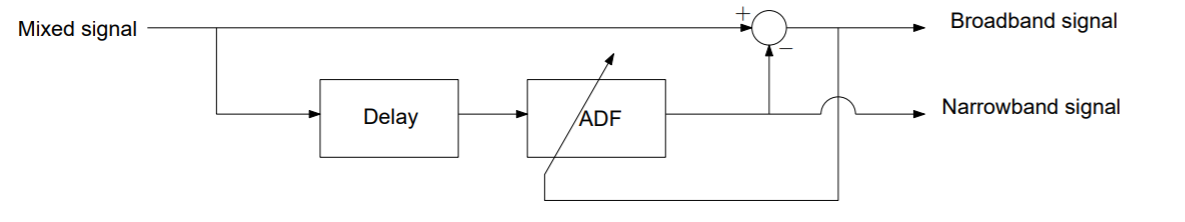

The input signal should be considered as $x_n =S_n +{\textrm{noise}}_n$.

The signal $x\left(n\right)$which is fed into the filter is delayed by D samples, where the delay D is chosen sufficiently large so that the wideband signal component $S_n +S_{n-D}$ are uncorrelated. This is the importance of the delay in this design.

We therefore obtain at the output of the filter, with a hat indicating an estimate:


$$\hat{{\textrm{noise}}_n } =\sum_{j=0}^N h_j^n x_{n-j-D}$$


The error signal can therefore be considered as:


$${e_n =\;S}_n +{\textrm{noise}}_n -\hat{{\textrm{noise}}_n }$$


(Note that this shows why we configured the error signal previously. Otherwise, we would get the negative of the broadband signal as the error output)

The minimisation of the sum of squared errors leads us back to the equations for determing the optimum coefficients. The LMS algorithm for adjusting the coeffcients recursively becomes:


$$\hat{h_j^{n+1} } =\hat{h_j^n } +\alpha \;e_n x_{n-j-D}$$
   
$$j=0,1,\ldotp \ldotp N$$


The algorithm was implemented in the following piece of MATLAB code. Unfortunately, issues were found in implementing the delay of the signal, despite attempts made.

At a certain point, we should be able to assume that the filter coefficients will stay reasonably constant, which would mean convergence has been reached. At this point, it is not necessary to continue computing filter coefficients as it is computationally intensive. If time allowed, a convergence mechanism would have been implemented in the code.

[x,Fs] = audioread('noisy_voices.wav'); % The data is read in as the vector x, while the sampling frequency is read in as Fs

p=8; % Number of filter coefficients set to 8
a=[zeros(100,p); zeros(100,p)];
alph=0.1; %arbitrarily chosen step size
D=0; %delay
%algorithm is computationally intensive without convergence and so we take
%only the first 30000 samples.
for i=(p+1+D):30000 
    xflipped = flip(x(i-p-D:-D+i-1));
    noisehat = a(i,:)*xflipped  ; %noise n found as in equation  
    e(i) = x(i)-noisehat; %error found like in equation
    xflipped2 = flip(x(i-p+1-D:i-D));
    a(i+1,:)=a(i,:)+(alph*e(i))*xflipped2'; %update filter coefficients,like equation
end
%player = audioplayer(5*xfiltered,Fs); %UNCOMMENT THESE TO HEAR FILTERED SIGNAL.
%play(player)

We clearly hear the filtered signal as having heavily attenuated the noise frequency, indicating that our implementation of the algorithm has been reasonably succesful. However, the noise is still present, which is likely due to the fact that the delay is not implemented properly in the code. 

We can view the signal in the time domain and see what kind of response we get.

figure
t1=0:1/Fs:length(e)*1/Fs-1/Fs; %time vector, in seconds for filtered
subplot(211)
plot(t1,e); %filter output
title("Filtered Sound file in Time domain with time domain approach");
xlabel('Time (s)') 
ylabel('Amplitude') 
t=0:1/Fs:length(x)*1/Fs-1/Fs; %time vector, in seconds for original
subplot(212)
plot(t,x); %original output
title("Original Sound file in Time domain with time domain appraoch");
xlabel('Time (s)') 
ylabel('Amplitude') 
xlim([0 3.75])

As we can see, the performance of the filter improves as time goes on, as we see large amplitudes at the beginning. This should be expected with such a recursive algorithm.